Estoy probando a utilizar los pesos a cada layer (encontré los pesos en el paper)

clc; clear all; close all;

img_path = fullfile('Codes','OD_circle_SQ_9_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

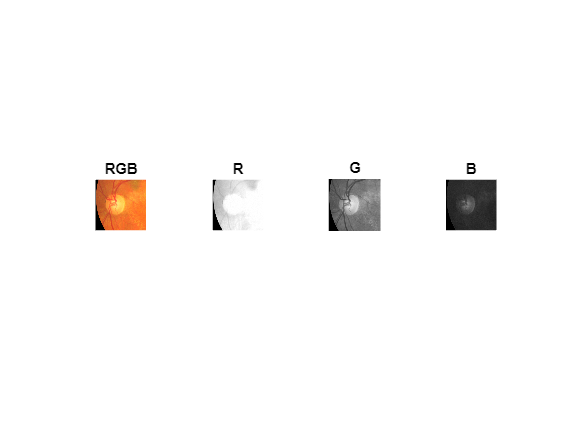

RGB = imread(string(fullfile(img_path, T{9,1})));%Aquí elijes la imagen
R=RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);
figure;
subplot(1, 4, 1);
imshow(RGB);
title('RGB');
subplot(1, 4, 2);
imshow(R);
title('R');
subplot(1, 4, 3);
imshow(G);
title('G');
subplot(1, 4, 4);
imshow(B);
title('B');

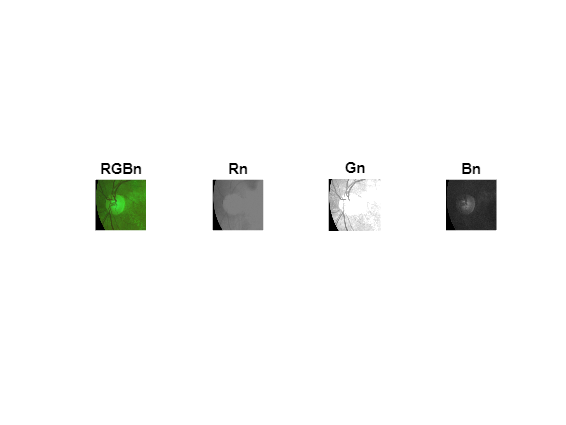

R=double(R);
G=double(G);
B=double(B);
Rn=R.*0.5;
Gn=G.*2;
Bn=B.*1;
RGBn = cat(3, Rn, Gn, Bn);
RGBn = RGBn./2;
RGBn=uint8(RGBn);
figure;
subplot(1, 4, 1);
imshow(uint8(RGBn));
title('RGBn');
subplot(1, 4, 2);
imshow(uint8(Rn));
title('Rn');
subplot(1, 4, 3);
imshow(uint8(Gn));
title('Gn');
subplot(1, 4, 4);
imshow(uint8(Bn));
title('Bn');

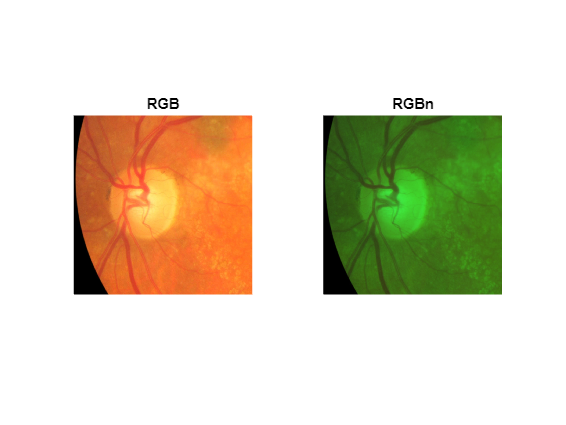

figure;
subplot(1, 2, 1);
imshow(RGB);
title('RGB');
subplot(1, 2, 2);
imshow(uint8(RGBn));
title('RGBn');

## **PROBANDO SUPERPIXEL**

Hago el superpixel grouping pa cada uno de ellos:

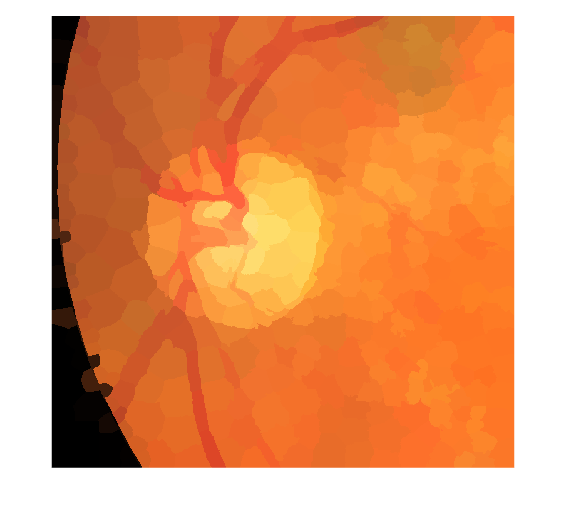

superpixelQuantity=400;
[L,N] = superpixels(RGB,superpixelQuantity, "NumIterations",150,"Compactness",1);

figure;
BW = boundarymask(L);
figure;
imshow(imoverlay(RGB,BW,'cyan'),'InitialMagnification',67);


outputImage = zeros(size(RGB),'like',RGB);
idx = label2idx(L);
numRows = size(RGB,1);
numCols = size(RGB,2);
for labelVal = 1:N
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(RGB(redIdx));
    outputImage(greenIdx) = mean(RGB(greenIdx));
    outputImage(blueIdx) = mean(RGB(blueIdx));
end    

figure
imshow(outputImage)

[L,N] = superpixels(RGBn,superpixelQuantity, "NumIterations",150,"Compactness",1);

figure;
BW = boundarymask(L);
figure;
imshow(imoverlay(RGBn,BW,'cyan'),'InitialMagnification',67);

outputImage = zeros(size(RGBn),'like',RGBn);
idx = label2idx(L);
numRows = size(RGBn,1);
numCols = size(RGBn,2);
for labelVal = 1:N
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(RGBn(redIdx));
    outputImage(greenIdx) = mean(RGBn(greenIdx));
    outputImage(blueIdx) = mean(RGBn(blueIdx));
end    

figure
imshow(outputImage)

Ig=rgb2gray(outputImage);
histogram(Ig);

thres=Ig>0.7*max(Ig(:));
out_thresed=double(outputImage).*thres;
imshow(uint8(out_thresed));
%EN EL 9 HA FUNCIONADO PERO NO ES UN MÉTODO EFECTIVO PARA USAR EN GENERAL
%EN UN CÓDIGO.

Voy a encontrar el brightest point, y el centro que más se le acerque será el del círculo del OD

PROBANDO A BUSCAR CÍRCULOS** Me pilla demasiados así qeu le tendré que hacer un preproccesing o algo**

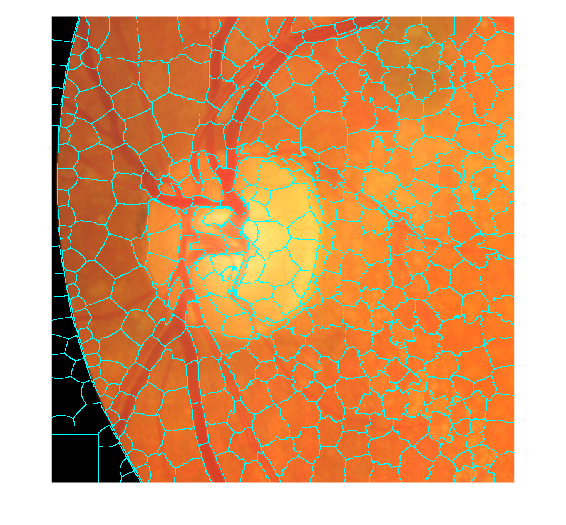

figure;
imshow(RGB);

stats = regionprops("table",double(rgb2gray(RGB)),"Centroid", ...
    "MajorAxisLength","MinorAxisLength","Orientation","Eccentricity","Circularity")
stats( stats.MajorAxisLength > 1000 | stats.MinorAxisLength < 300 | stats.Circularity < 1 | stats.Eccentricity < 0.7, : ) = []%he puesto esta linea que la he sacado de otro código, está 100x100 mal. Hay que poner and en vez de or!!!!!
centers = stats.Centroid;
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = stats.MinorAxisLength/2;%he usado el min axis en vez de diameter
hold on
viscircles(centers,radii)%aquí busca una manera de poder dibujar elipses en vez de circulos
hold off

**TODAVIA NO HE PROBADO ESTO PERO ES PARA PONER EL CÍRCULO BLACO **

% Definir el tamaño de la matriz
n = 1201;

% Crear una cuadrícula de coordenadas
[x, y] = meshgrid(1:n, 1:n);

% Definir los centros y los radios de los círculos
minorAxes = stats.MinorAxisLength;

% Crear una matriz para almacenar las imágenes de los círculos
numCircles = size(centers, 1);
binaryImages = zeros(n, n, numCircles);

% Crear las imágenes de los círculos
for i = 1:numCircles
    % Calcular la distancia de cada punto a la posición del centro
    distances = sqrt((x - centers(i, 1)).^2 + (y - centers(i, 2)).^2);

    % Crear la matriz binaria con el círculo en su interior
    binaryMatrix = distances <= minorAxes(i)/2;

    % Almacenar la imagen del círculo en la matriz
    binaryImages(:,:,i) = binaryMatrix;

    % Mostrar la imagen del círculo
    figure;
    imshow(binaryMatrix);
end